# **ECON 310: Dynamic Macroeconomics**

### **Spring 2025**

### **Fulbright University Vietnam**

%{

    run_vfi_sgml.mlx
    ----------------
    This code solves the stochastic growth model with endogenous labor supply using value function iteration.

%}

## Model: Stochastic Growth Model with Endogenous Labor.

The social planner's problem is


$$\underset{\{c_t\}_{t=1}^{\infty},\{n_t\}_{t=1}^{\infty},\{k_{t+1}\}_{t=1}^{\infty}}{\text{max }} \mathbb{E}_0\sum_{t=1}^\infty \beta^{t} \left[\frac{c_t^{1-\sigma}}{1-\sigma} + \gamma\frac{(1-n_t)^{1+\frac{1}{\nu}}}{1+\frac{1}{\nu}} \right] \text{ ,}$$


 
$$\begin{array}{r l} \text{s.t. } y_t = c_t+i_t \end{array} \ ,$$


 
$$\begin{array}{r l} y_t = A_t k_t^{\alpha}n_t^{1-\alpha} \end{array} \ ,$$


 
$$\begin{array}{r l} k_{t+1} = (1-\delta)k_t+ i_t \end{array} \ ,$$


 
$$\begin{array}{r l} \text{log}(A_{t+1}) = \mu + \rho\text{log}(A_t) + \epsilon_{t+1} \end{array} \ ,$$


 
$$\begin{array}{r l} 1 = n_t + l_t \end{array} \ ,$$



$$c_t > 0,  k_t > 0 \ ,$$


where $|\rho| < 1$, $\epsilon_{t+1}\sim\mathcal{N}(0,\sigma^2_{\epsilon})$, and the constraints are for $t = 1, 2, ...,$. The rationale for the constraints that are similar to those in the stochastic growth model. The second to the last line is the time constraint: given an endowment of one unit of time, part of it can go to labor $n_t$ and the rest will go to leisure $l_t$. Consumers derive utility from leisure but must supply labor to produce the final good. The choice of utility functions for consumption and leisure are assumptions based on the literature; other functions exist and will be discussed when discussing households in greater detail.

## Recursive Formulation.

The recursive formulation, combining the constraints into one, is


$$V_t(k_t,A_t) = \underset{c_t, n_t, k_{t+1}}{\text{max}}\frac{c_t^{1-\sigma}}{1-\sigma} + \gamma\frac{(1-n_t)^{1+\frac{1}{\nu}}}{1+\frac{1}{\nu}} + \beta \mathbb{E}_t\left[V_{t+1}(k_{t+1},A_{t+1})\right] \ ,$$


 
$$\begin{array}{r l} \text{s.t. } A_tk_t^{\alpha}n_t^{1-\alpha} =  c_t + k_{t+1} - (1-\delta)k_t\end{array} \ \text{for} \ t = 1, 2, ... \ ,$$


 
$$\begin{array}{r l} \text{log}(A_{t+1}) = \mu + \rho\text{log}(A_t) + \epsilon_{t+1} \end{array} \ ,$$


 
$$\begin{array}{r l} 1 = n_t + l_t \end{array} \ ,$$



$$c_t > 0,  k_t > 0 \text{ .}$$


Because of the labor supply choice, the choice space has now expanded to include this. Substituting the combined constraint into the utility function gives


$$V_t(k_t,A_t) = \underset{n_t,k_{t+1}}{\text{max}}\frac{\left(A_tk_t^{\alpha}n_t^{1-\alpha}+(1-\delta)k_t-k_{t+1}\right)^{1-\sigma}}{1-\sigma} + \gamma\frac{(1-n_t)^{1+\frac{1}{\nu}}}{1+\frac{1}{\nu}} + \beta \mathbb{E}_t\left[V_{t+1}(k_{t+1},A_{t+1})\right] \ ,$$


 
$$\begin{array}{r l} \text{s.t. log}(A_{t+1}) = \mu + \rho\text{log}(A_t) + \epsilon_{t+1} \end{array} \ ,$$


 
$$\begin{array}{r l} 1 = n_t + l_t \end{array} \ ,$$



$$k_t > 0 \ ,$$


simplifying the problem slightly.

## Set up directories and paths.

clc
clear
close all

id = getenv('USERNAME'); % Gets your username.

main = strcat('/Users/nguyenhoangminh/Desktop/ps1 - test'); % Project Folder.
cd (strcat(main)) % Set project folder as current working directory.

addpath(genpath(main)) % Add all subfolders in current working directory to path. Note: Make sure file names are unique.
figout = strcat(main,'/output/figures/'); % Folder for figures.

fprintf('The directory is %s \n\n',main)

The directory is /Users/nguyenhoangminh/Desktop/ps1 - test 



## Set the parameters and generate the state space.

Calls: model.m.

As before, we cannot directly compute the steady state capital because of the productivity fluctuations, but we can still build the grid for $k_t$ around the deterministic steady state.

par = model.setup; % Set parameters.
par = model.gen_grids(par); % Generate the state space.

## Solve the model using Value Function Iteration.

Calls: solve.m, and model.m.

Note that the allocation of labor and leisure is a static decision. From (5.23) in Adda and Cooper, the intratemporal condition is


$$(A_tk_t^{\alpha}n_t^{1-\alpha}+(1-\delta)k_{t}-k_{t+1})^{-\sigma}A_t(1-\alpha)k_t^{\alpha}n_t^{-\alpha} = -\gamma(1-n_t)^{\frac{1}{\nu}} \ .$$


We have pre-determined grids for $k_t$ and $A_t$, and we use the same grid for $k_{t+1}$ as $k_t$. Given these and the equation above, we can $n_t$ by using a numerical solver to minimize


$$f(n_t) = (A_tk_t^{\alpha}n_t^{1-\alpha}+(1-\delta)k_{t}-k_{t+1})^{-\sigma}A_t(1-\alpha)k_t^{\alpha}n_t^{-\alpha} + \gamma(1-n_t)^{\frac{1}{\nu}} \ ,$$


and obtain optimal labor supply given any combination of the state variables and any potential choice of $k_{t+1}$ associated with these. Crucially, we can do this outside of the value function iteration algorithm because the decision is static. Once we have the optimal $n_t$, we can treat this as a parameter for each combination of $k_t, k_{t+1},$ and $A_t$.

t = cputime;
sol = solve.grow(par); % Solve the model using Value Function Iteration.

------------Beginning Value Function Iteration.------------

Iteration: 25.
Iteration: 50.
Iteration: 75.
Iteration: 100.
Iteration: 125.
Iteration: 150.
Iteration: 175.
Iteration: 200.
Iteration: 225.
Iteration: 250.
Iteration: 275.
Iteration: 300.
Iteration: 325.
Iteration: 350.
Iteration: 375.
Iteration: 400.
Iteration: 425.
Iteration: 450.
Iteration: 475.

Converged in 498 iterations.

------------End of Value Function Iteration.------------


fprintf('\nModel solved in %0.4f seconds.\n',cputime-t)


Model solved in 4.8700 seconds.


## Simulate the model and plot the model functions and time series.

Calls: simulate.m and my_graph.m.

The model functions behave in a similarly to those in the stochastic growth model. The difference now is that labor supply is negatively correlated with productivity. This is because when $A_t$ is low, labor supply increases to boost output; when $A_t$ is high, less labor is needed to produce a given level of output and more time can be spent on leisure. Given a Cobb-Douglas production function with constant returns to scale, the marginal product of labor is increasing with capital so $n_t$ increases with $k_t$.

The time series data have similar qualitative results as in the model without labor supply. Labor itself is relatively constant (see the units of the graph). 

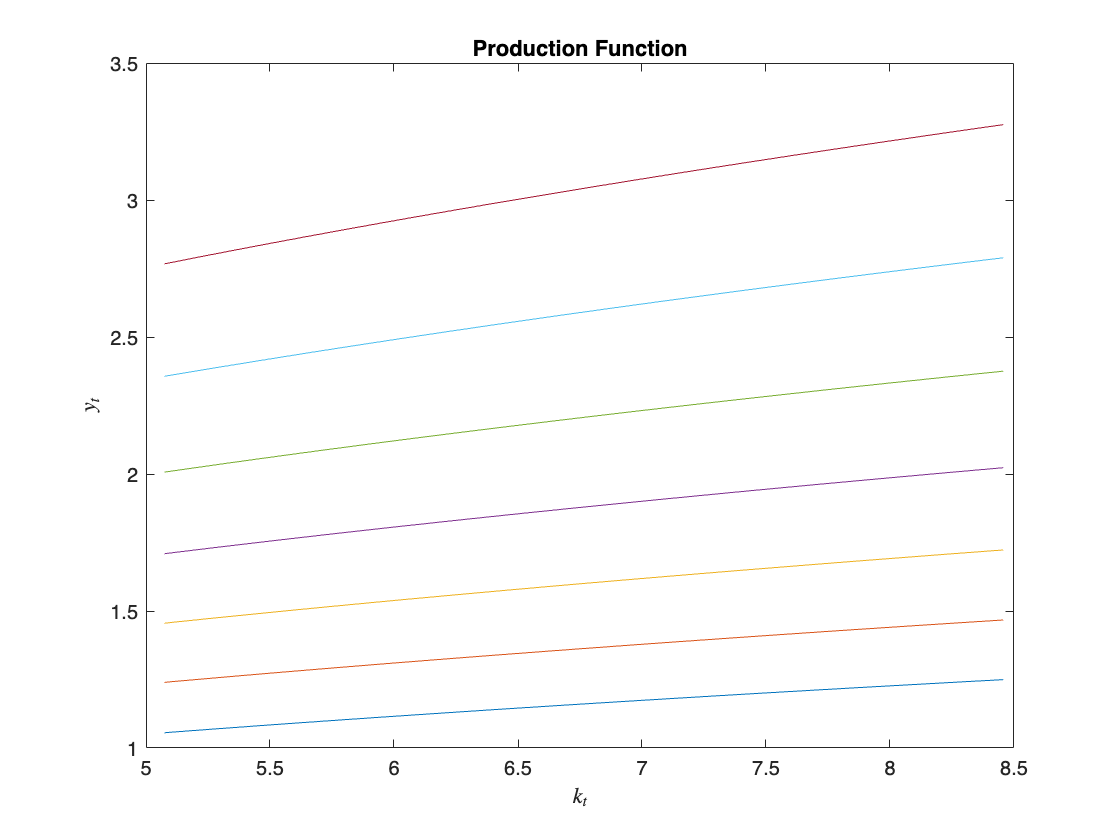

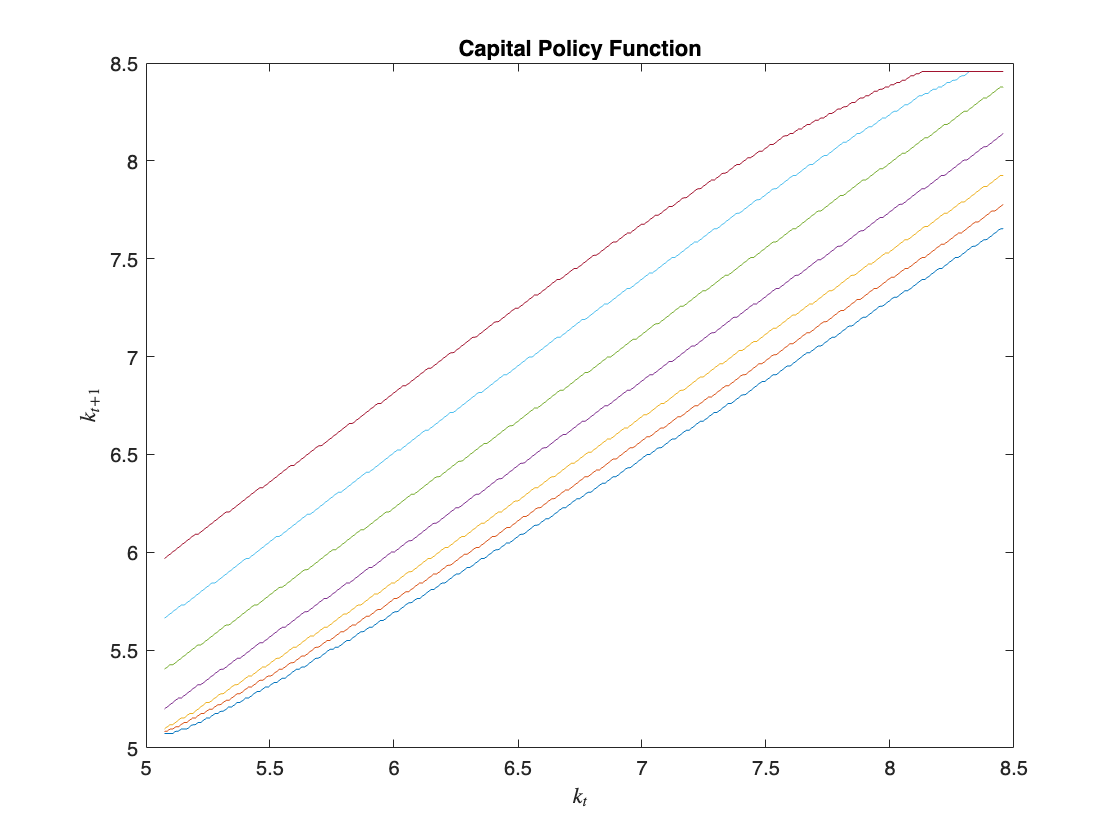

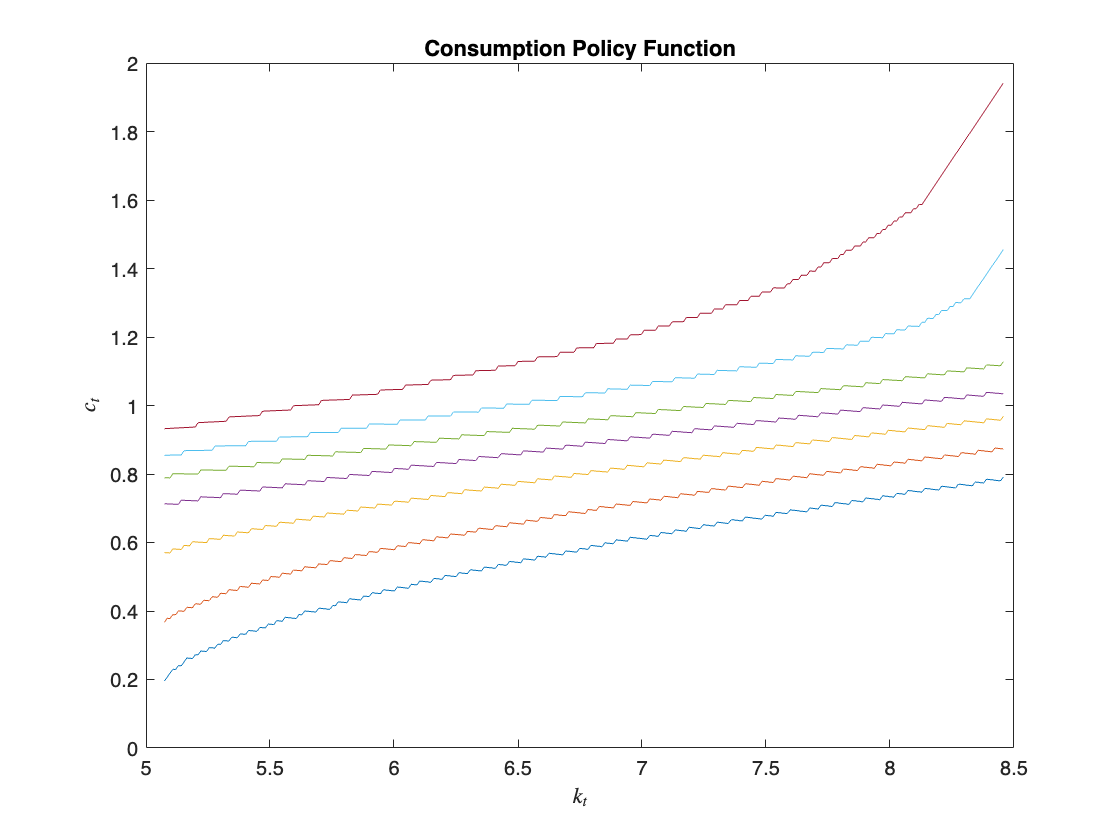

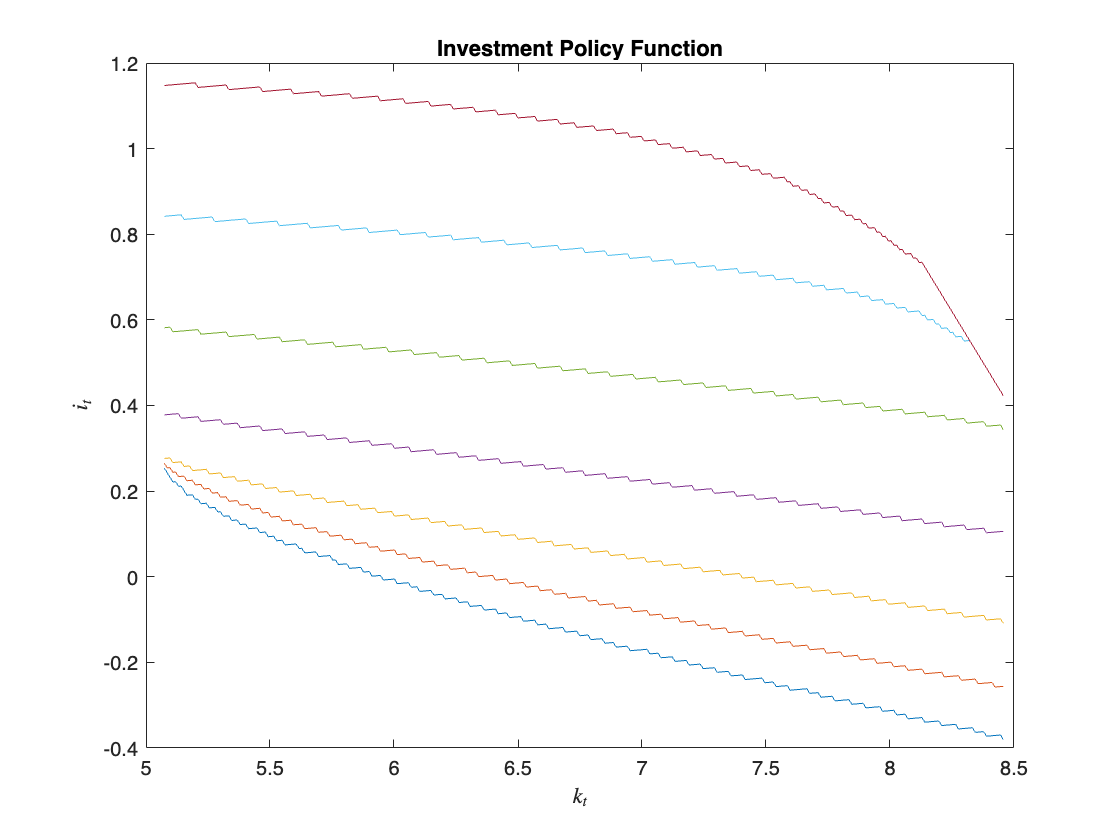

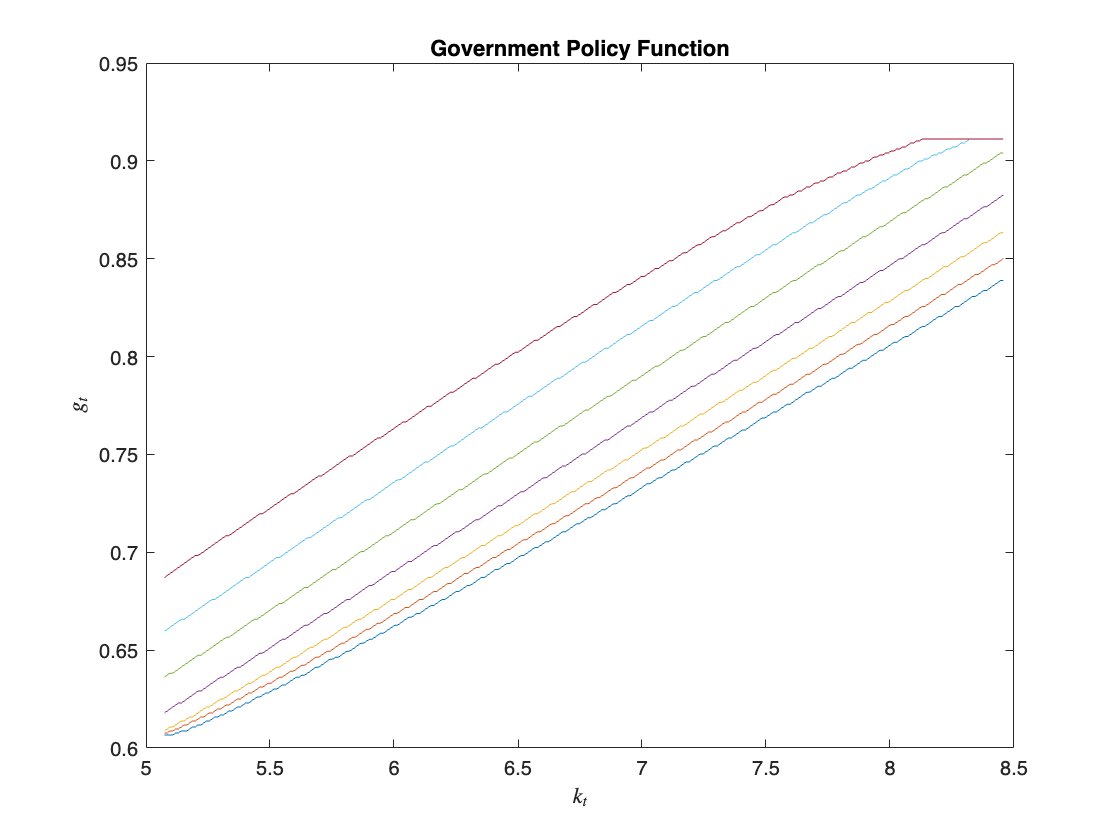

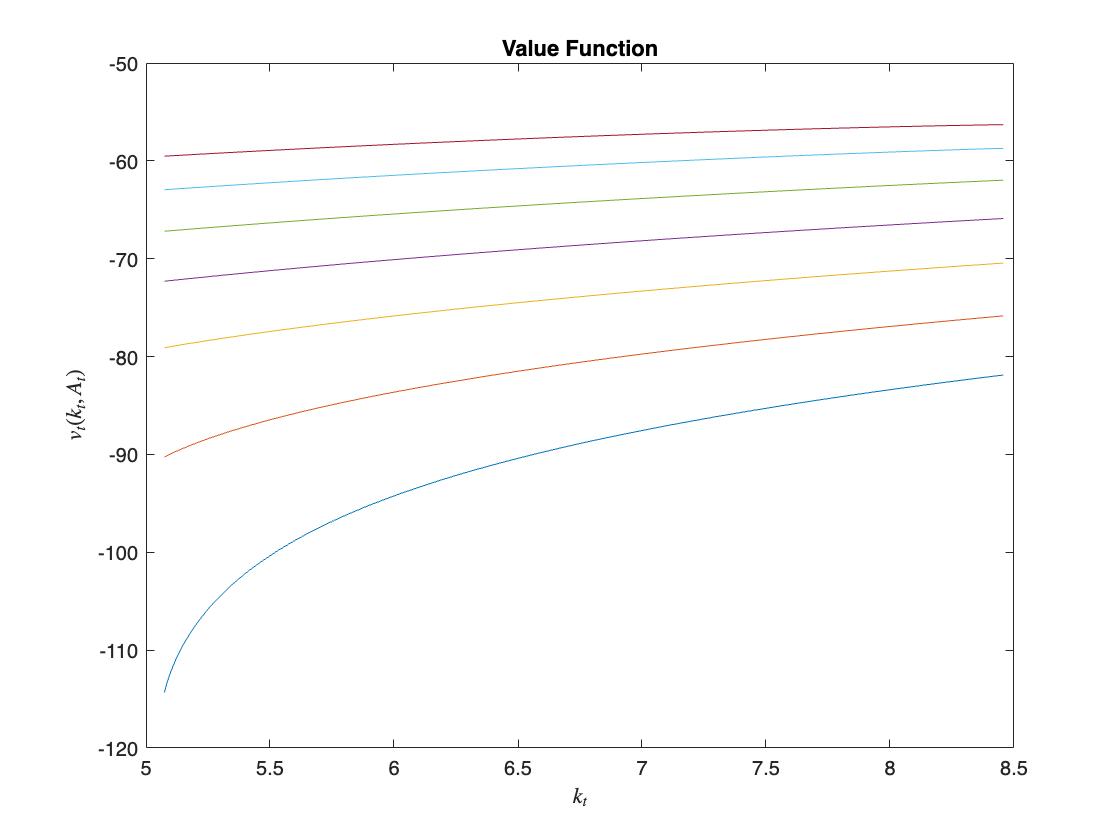

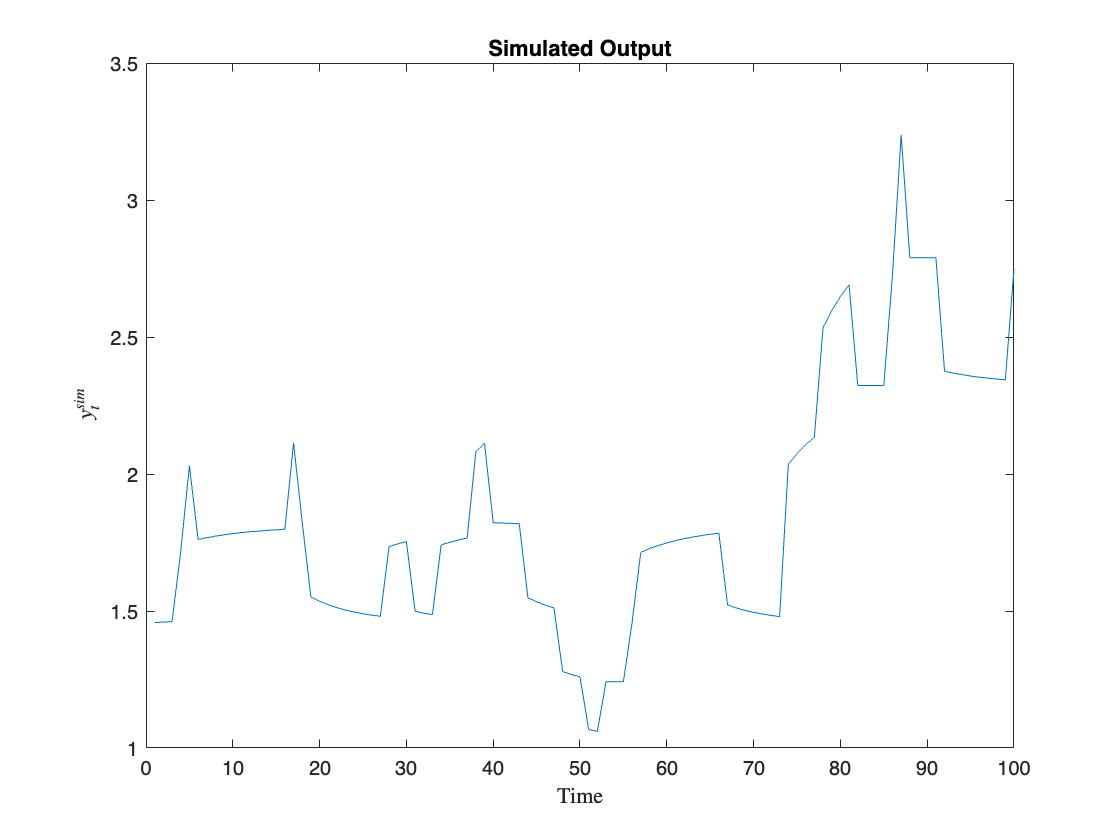

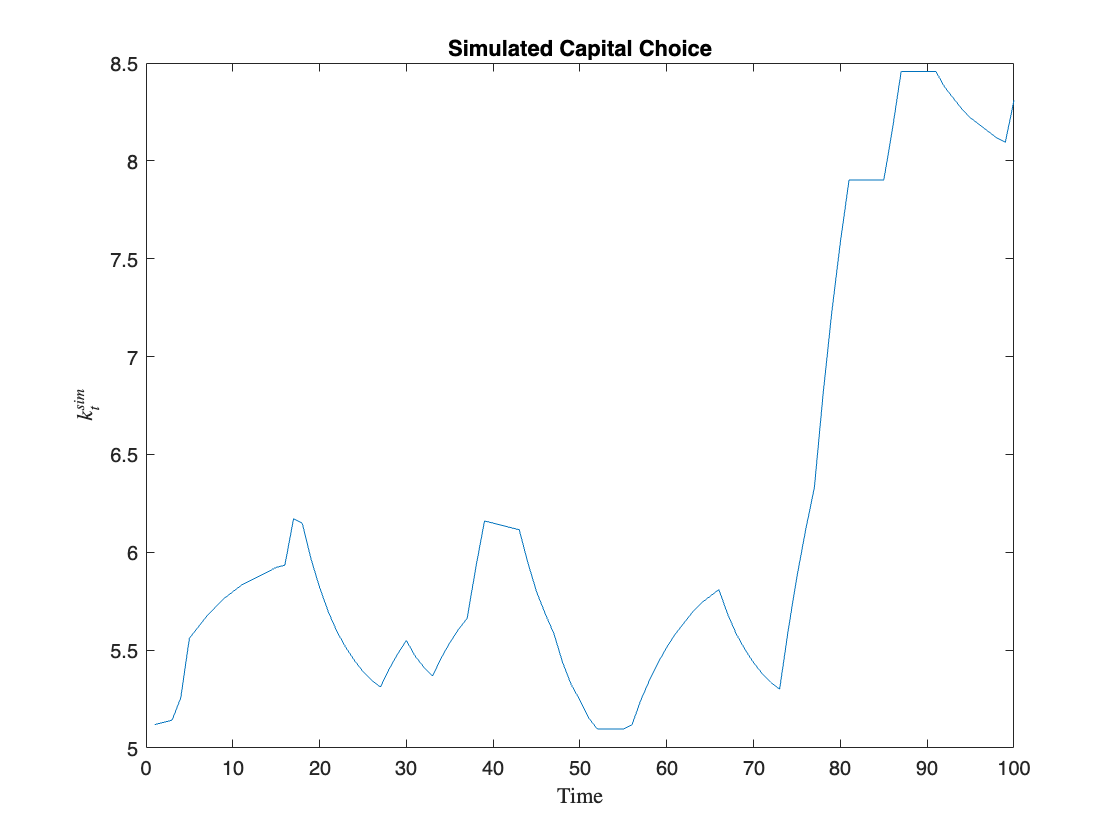

sim = simulate.grow(par,sol); % Simulate the model.
my_graph.plot_policy(par,sol,sim,figout) % Plot the model functions and time series.

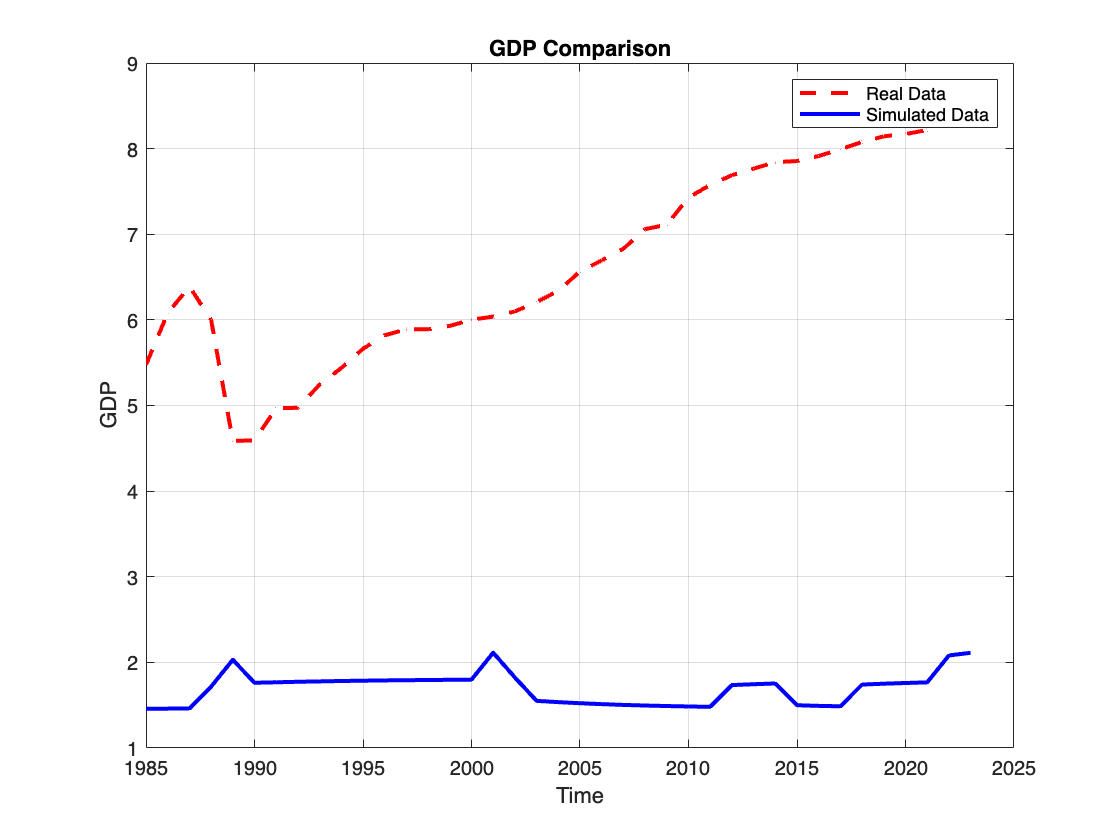

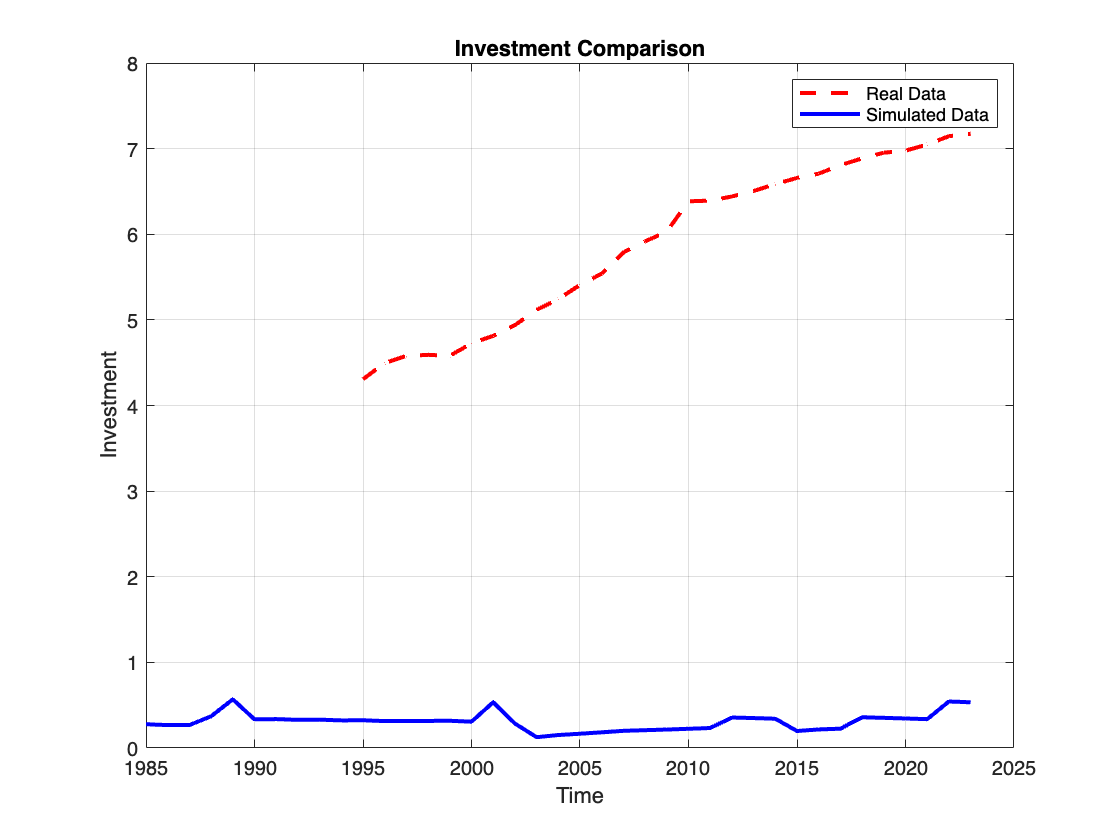

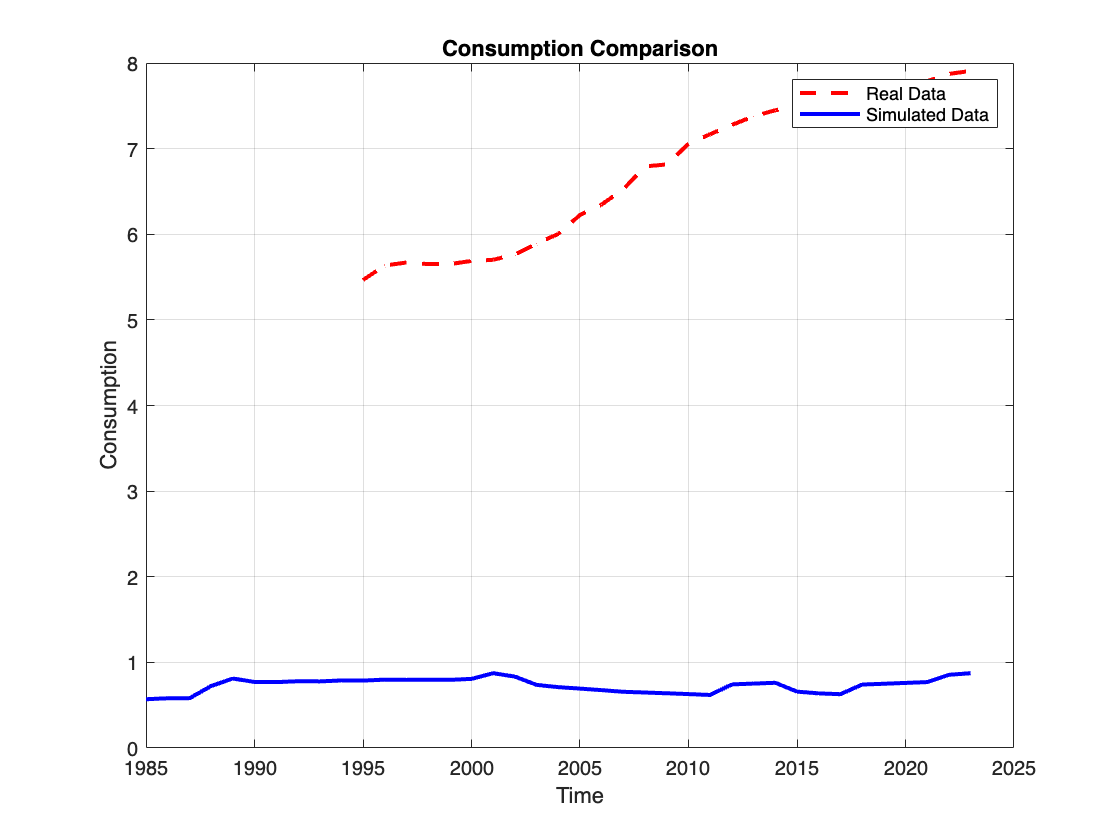

--- Descriptive Statistics for Simulated vs Real Data ---
                      Mean_Real    Mean_Simulated    Std_Dev_Real    Std_Dev_Simulated    Maximum_Real    Maximum_Simulated    Minimum_Real    Minium_Simulated
                      _________    ______________    ____________    _________________    ____________    _________________    ____________    ________________

    GDP per capita     6.6473          1.6969           1.1442              0.188            8.3622             2.1132            4.5861            1.4577     
    Investment         1.7593         0.30737          0.16952            0.10411            1.9702            0.56823            1.4601           0.12643 

my_graph.compare_real_vs_simulated(par, sim)

## Analysis.

To check the validity of the model, we compute statistics of interest and see how the data line up. In some cases, these are explicitly targeted by adjusting or estimating parameters that govern the behavior of the simulated data. In our case, we just set these exogenously from the literature, which in turn obtain these from data or estimation. The model differs from the literature so this model is off from the data, see Table 5.1 in Adda and Cooper.

% Compute the variables corresponding to data. The model assumes the data are detrended.

ysim = sim.ysim; % Output.
ksim = sim.ksim; % Capital Stock.
gsim = sim.gsim; % Government Spending.
isim = sim.isim; % Investment.
csim = sim.csim; % Consumption.
w = (1-par.alpha).*sim.Asim.*ksim.^(par.alpha); % Wages = MPL.

% Std. Dev of variables relative to output.

cvar = sqrt(var(csim))/sqrt(var(ysim));
ivar = sqrt(var(isim))/sqrt(var(ysim));
gvar = sqrt(var(gsim))/sqrt(var(ysim));
wvar = sqrt(var(w))/sqrt(var(ysim));

fprintf('The Std. Dev of Consumption Relative to Output is: %0.4f',cvar)

The Std. Dev of Consumption Relative to Output is: 0.5583

fprintf('The Std. Dev of Investment Relative to Output is: %0.4f',ivar)

The Std. Dev of Investment Relative to Output is: 0.3243

fprintf('The Std. Dev of Government Spending Relative to Output is: %0.4f',gvar)

The Std. Dev of Government Spending Relative to Output is: 0.2208

fprintf('The Std. Dev of Real Wages Relative to Output is: %0.4f',wvar)

The Std. Dev of Real Wages Relative to Output is: 0.6820

## Counterfactual Exercise - Fiscal Policy

To check the validity of our statement in exerise b, we will conduct a counterfactual exercise that tests the simulated output at different tax rates (fiscal policy).

%% Simulate the model for different tau_k levels

% Base tau_k level from model.m
base_tau_k = model.setup().tau_k;

% Define different tau_k levels for comparison
tau_k_levels = [0.05, 0.1, 0.15, 0.20, 0.25];  % Example tau_k values for comparison

% Structure to store results for each tau_k
results = struct();

for i = 1:length(tau_k_levels)
    % Update tau_k for the simulation
    par = model.setup();
    par.tau_k = tau_k_levels(i);  % Change tau_k to the current level
    
    % Generate grids and solve the model for this tau_k level
    par = model.gen_grids(par);  % Update the grids based on new tau_k
    sol = solve.grow(par);  % Solve the model using Value Function Iteration
    
    % Simulate the model for the given tau_k
    sim = simulate.grow(par, sol);
    
    % Store the results
    results(i).tau_k = tau_k_levels(i);
    results(i).ysim = sim.ysim;
    results(i).ksim = sim.ksim;
    results(i).isim = sim.isim;
    results(i).csim = sim.csim;

    results(i).stats.mean_ysim = mean(sim.ysim);
    results(i).stats.std_ysim = std(sim.ysim);
    results(i).stats.min_ysim = min(sim.ysim);
    results(i).stats.max_ysim = max(sim.ysim);

    results(i).stats.mean_ksim = mean(sim.ksim);
    results(i).stats.std_ksim = std(sim.ksim);
    results(i).stats.min_ksim = min(sim.ksim);
    results(i).stats.max_ksim = max(sim.ksim);

    results(i).stats.mean_isim = mean(sim.isim);
    results(i).stats.std_isim = std(sim.isim);
    results(i).stats.min_isim = min(sim.isim);
    results(i).stats.max_isim = max(sim.isim);

    results(i).stats.mean_csim = mean(sim.csim);
    results(i).stats.std_csim = std(sim.csim);
    results(i).stats.min_csim = min(sim.csim);
    results(i).stats.max_csim = max(sim.csim);

    fprintf('Tau_k = %.2f:\n', tau_k_levels(i));
    fprintf('Output: Mean = %.4f, Std = %.4f, Min = %.4f, Max = %.4f\n', ...
        results(i).stats.mean_ysim, results(i).stats.std_ysim, ...
        results(i).stats.min_ysim, results(i).stats.max_ysim);
    fprintf('Capital: Mean = %.4f, Std = %.4f, Min = %.4f, Max = %.4f\n\n', ...
        results(i).stats.mean_ksim, results(i).stats.std_ksim, ...
        results(i).stats.min_ksim, results(i).stats.max_ksim);
    fprintf('Investment: Mean = %.4f, Std = %.4f, Min = %.4f, Max = %.4f\n', ...
        results(i).stats.mean_isim, results(i).stats.std_isim, ...
        results(i).stats.min_isim, results(i).stats.max_isim);
    fprintf('Consumption: Mean = %.4f, Std = %.4f, Min = %.4f, Max = %.4f\n\n', ...
        results(i).stats.mean_csim, results(i).stats.std_csim, ...
        results(i).stats.min_csim, results(i).stats.max_csim);
end

------------Beginning Value Function Iteration.------------

Iteration: 25.
Iteration: 50.
Iteration: 75.
Iteration: 100.
Iteration: 125.
Iteration: 150.
Iteration: 175.
Iteration: 200.
Iteration: 225.
Iteration: 250.
Iteration: 275.
Iteration: 300.
Iteration: 325.
Iteration: 350.
Iteration: 375.
Iteration: 400.

Converged in 404 iterations.

------------End of Value Function Iteration.------------


Tau_k = 0.05:


Output: Mean = 2.0493, Std = 0.3969, Min = 1.2299, Max = 3.2750


Capital: Mean = 8.4090, Std = 0.1423, Min = 7.8234, Max = 8.4569



Investment: Mean = 0.4252, Std = 0.0506, Min = 0.2096, Max = 0.6587


Consumption: Mean = 1.2849, Std = 0.3889, Min = 0.6922, Max = 2.5119



------------Beginning Value Function Iteration.------------

Iteration: 25.
Iteration: 50.
Iteration: 75.
Iteration: 100.
Iteration: 125.
Iteration: 150.
Iteration: 175.
Iteration: 200.
Iteration: 225.
Iteration: 250.
Iteration: 275.
Iteration: 300.
Iteration: 325.
Iteration: 350.
Iteration: 375.

Converged in 395 iterations.

------------End of Value Function Iteration.------------


Tau_k = 0.10:


Output: Mean = 2.0182, Std = 0.4133, Min = 1.1769, Max = 3.2750


Capital: Mean = 8.0189, Std = 0.5989, Min = 6.2847, Max = 8.4569



Investment: Mean = 0.4225, Std = 0.1251, Min = 0.0088, Max = 0.8245


Consumption: Mean = 1.0848, Std = 0.3596, Min = 0.6878, Max = 2.3216



------------Beginning Value Function Iteration.------------

Iteration: 25.
Iteration: 50.
Iteration: 75.
Iteration: 100.
Iteration: 125.
Iteration: 150.
Iteration: 175.
Iteration: 200.
Iteration: 225.
Iteration: 250.
Iteration: 275.
Iteration: 300.
Iteration: 325.
Iteration: 350.
Iteration: 375.

Converged in 383 iterations.

------------End of Value Function Iteration.------------


Tau_k = 0.15:


Output: Mean = 1.9196, Std = 0.4434, Min = 1.0917, Max = 3.2750


Capital: Mean = 6.8531, Std = 1.0099, Min = 5.1420, Max = 8.4569



Investment: Mean = 0.3747, Std = 0.1618, Min = 0.0122, Max = 0.8556


Consumption: Mean = 0.9323, Std = 0.2944, Min = 0.5112, Max = 2.1313



------------Beginning Value Function Iteration.------------

Iteration: 25.
Iteration: 50.
Iteration: 75.
Iteration: 100.
Iteration: 125.
Iteration: 150.
Iteration: 175.
Iteration: 200.
Iteration: 225.
Iteration: 250.
Iteration: 275.
Iteration: 300.
Iteration: 325.
Iteration: 350.
Iteration: 375.
Iteration: 400.
Iteration: 425.
Iteration: 450.
Iteration: 475.

Converged in 498 iterations.

------------End of Value Function Iteration.------------


Tau_k = 0.20:


Output: Mean = 1.8557, Std = 0.4464, Min = 1.0611, Max = 3.2370


Capital: Mean = 6.1730, Std = 1.0950, Min = 5.0968, Max = 8.4569



Investment: Mean = 0.3392, Std = 0.1448, Min = 0.1264, Max = 0.7917


Consumption: Mean = 0.8110, Std = 0.2492, Min = 0.2513, Max = 1.6235



------------Beginning Value Function Iteration.------------


Converged in 2 iterations.

------------End of Value Function Iteration.------------


Tau_k = 0.25:


Output: Mean = 1.8607, Std = 0.4311, Min = 1.1089, Max = 3.2191


Capital: Mean = 6.2339, Std = 0.9857, Min = 5.1420, Max = 8.3664



Investment: Mean = 0.3301, Std = 0.1411, Min = -0.1694, Max = 0.8098


Consumption: Mean = 0.6793, Std = 0.2702, Min = 0.1767, Max = 1.3871



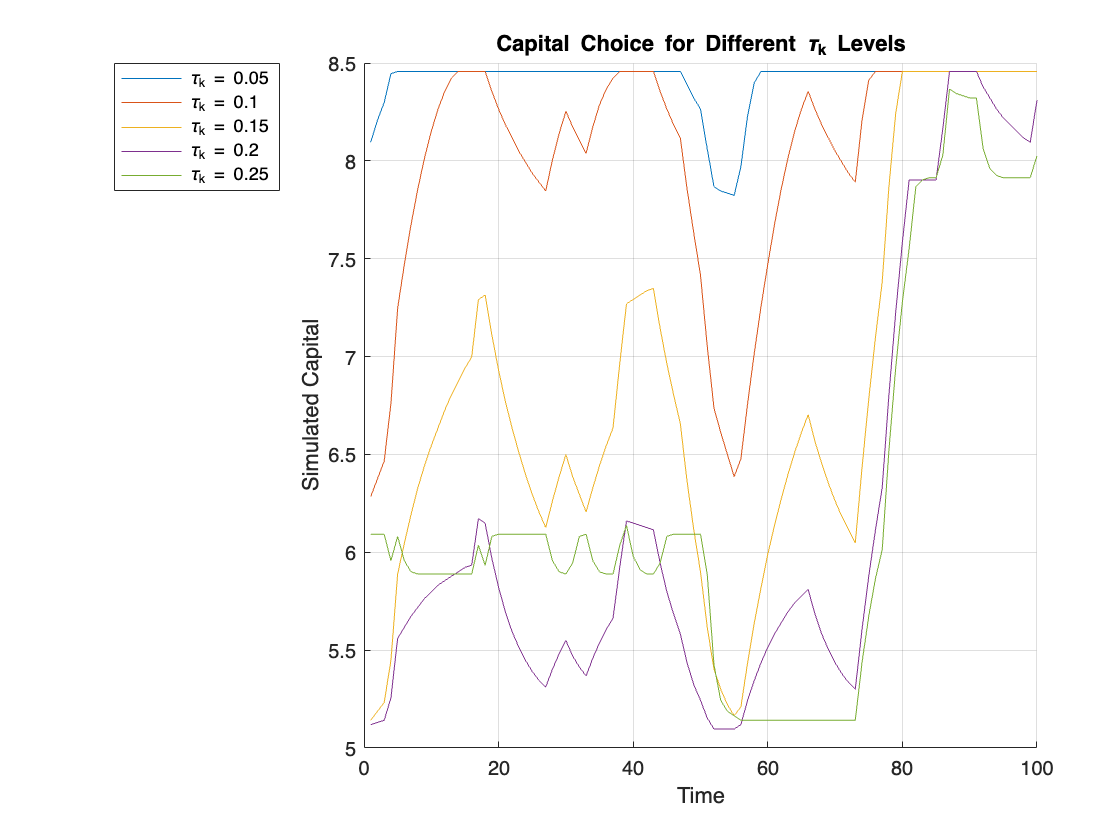


%% Plot the results for different tau_k levels

figure;
hold on;
for i = 1:length(tau_k_levels)
    plot(results(i).ksim, 'DisplayName', ['\tau_k = ' num2str(results(i).tau_k)]);
end
xlabel('Time');
ylabel('Simulated Capital');
title('Capital Choice for Different \tau_k Levels');
legend('Location', 'northwestoutside');
grid on;

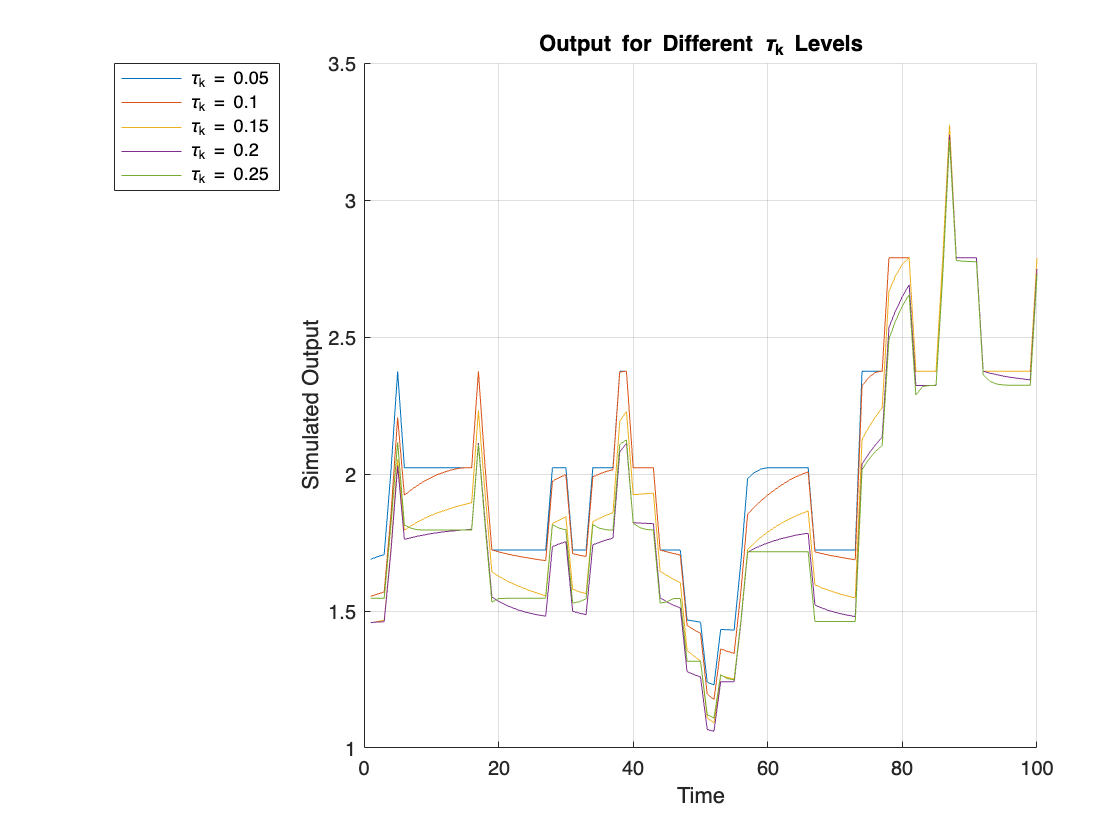


figure;
hold on;
for i = 1:length(tau_k_levels)
    plot(results(i).ysim, 'DisplayName', ['\tau_k = ' num2str(results(i).tau_k)]);
end
xlabel('Time');
ylabel('Simulated Output');
title('Output for Different \tau_k Levels');
legend('Location', 'northwestoutside');
grid on;

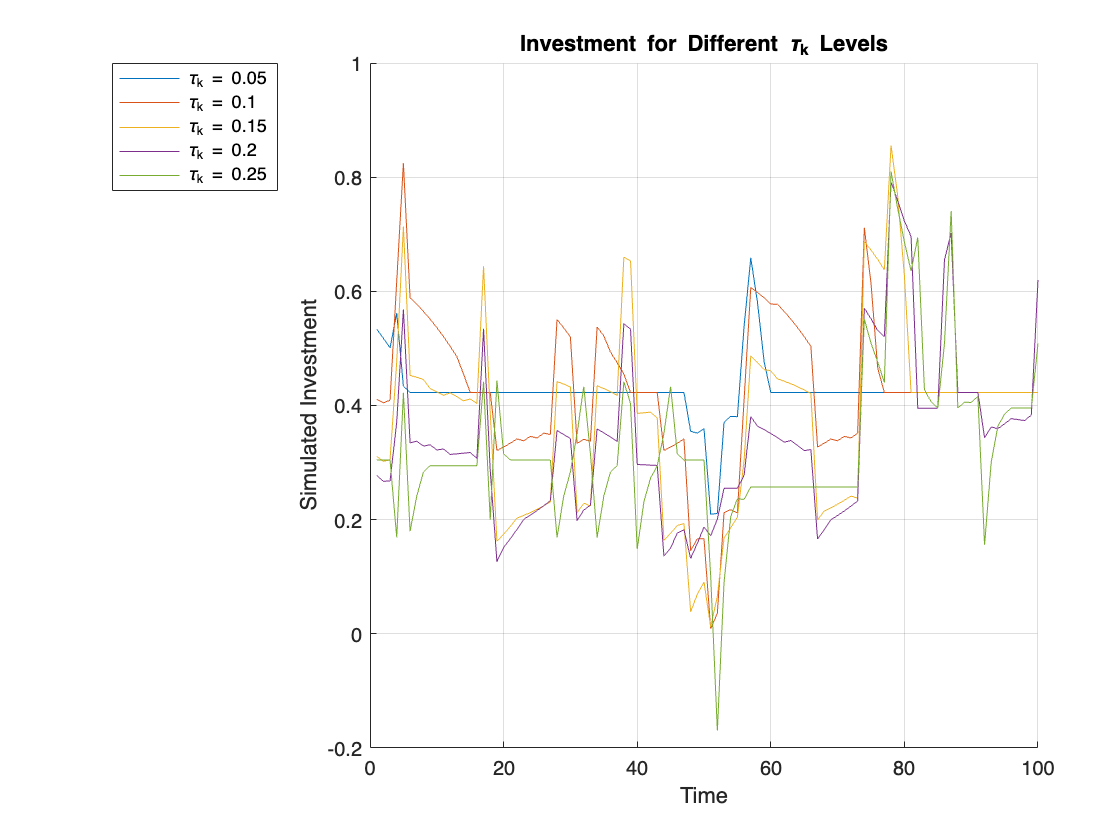

figure;
hold on;
for i = 1:length(tau_k_levels)
    plot(results(i).isim, 'DisplayName', ['\tau_k = ' num2str(results(i).tau_k)]);
end
xlabel('Time');
ylabel('Simulated Investment');
title('Investment for Different \tau_k Levels');
legend('Location', 'northwestoutside');
grid on;

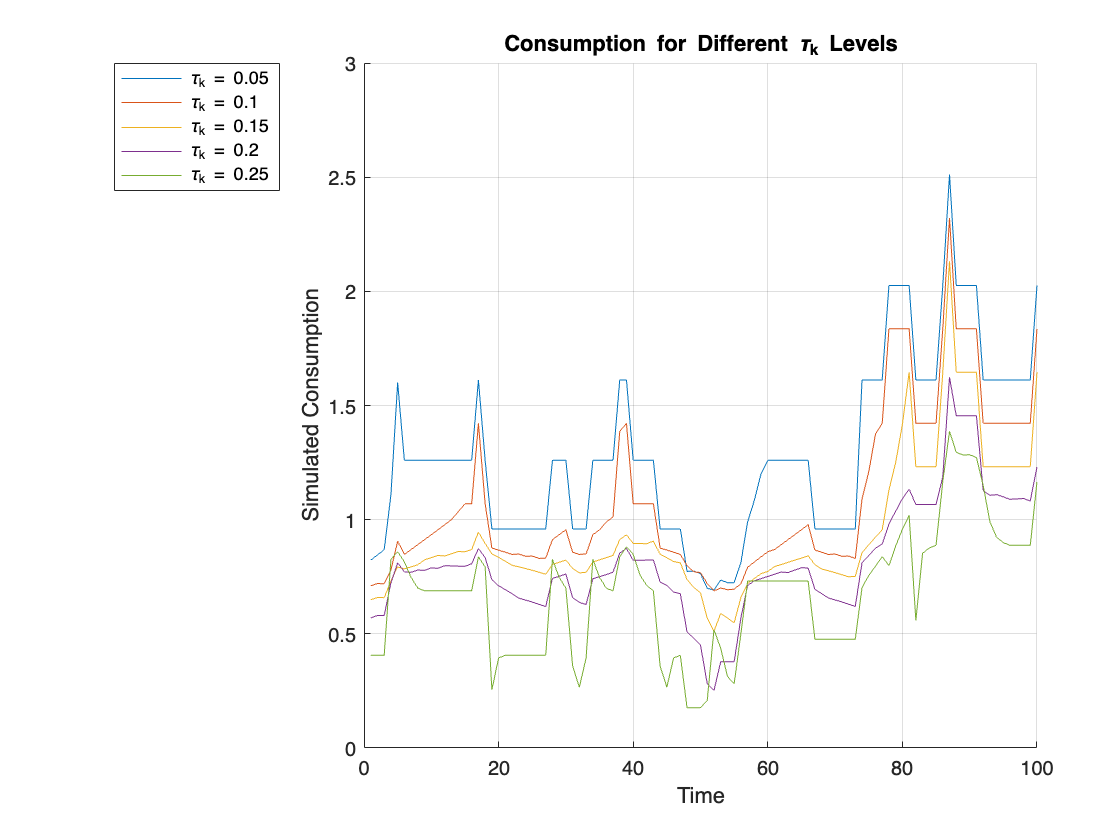

figure;
hold on;
for i = 1:length(tau_k_levels)
    plot(results(i).csim, 'DisplayName', ['\tau_k = ' num2str(results(i).tau_k)]);
end
xlabel('Time');
ylabel('Simulated Consumption');
title('Consumption for Different \tau_k Levels');
legend('Location', 'northwestoutside');
grid on;